# Venus

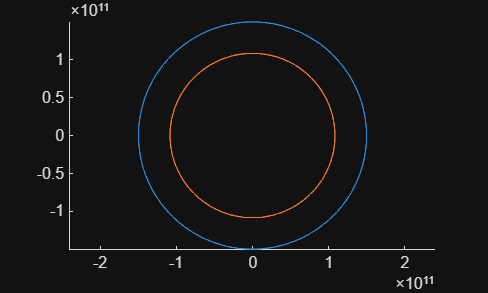

clear all, close all, clc, clf  
r_Mars  = 227990000*10^3;  % Mittlerer Bahnradius Mars 
T_Mars = 686.980; % Tage

tspan = linspace(0,365.25,365.25);

Earth = posEarth(tspan);
Venus = posVenus(tspan);

figure;
hold on;
plot(Earth(:,1), Earth(:,2));
plot(Venus(:,1), Venus(:,2));
axis equal;

Abstand 1% und so

%Startposition der Venus abgreifen
rV = posVenus(0)';
d = linspace(1e5, 1e12, 100000);   % 100 km – 1 Mio km
ratio = zeros(size(d));
for i = 1:length(d)     %Stattdessen mit fzero?
    r_test = rV + [0; d(i)];
    
    y_all = [r_test; 0; 0];
    [~, a_S, a_E, a_V] = grav_calc(0, y_all);
    a_total = a_S + a_E + a_V;
    ratio(i) = norm(a_V) / norm(a_total);
    if ratio(i) <= 0.01
        dist_in_km = d(i) / 1000;
        disp(dist_in_km)
        fprintf("%.2f", ratio(i))
        break
    end
end

   1.7001e+06



0.01

Bahnkurve Sonde, Start tangential zu Erdlaufbahn

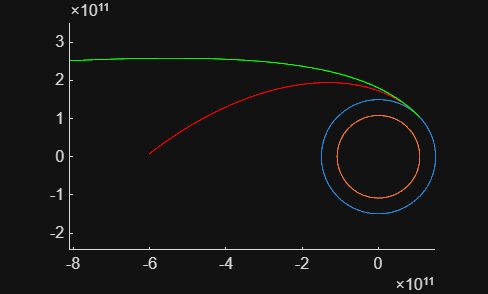

diam_earth = 12742 * 10^3; %Erdumfang in Metern 
angle_tan = 0.7724 + pi/2;
w_earth = 2*pi / 365.256; %Winkelgeschwindigkeit Erde
r_earth  = 149597870*10^3; %Radius Erde in Metern
v_earth = w_earth * r_earth;
v0_sonde = 15 * 10^3 * 86400 + v_earth;      %Startgeschwindigkeit in Metern/Tage

start_sonde = posEarth(0);
start_sonde(1) = start_sonde(1) + cos(angle_tan) * diam_earth / 2;
start_sonde(2) = start_sonde(2) + sin(angle_tan) * diam_earth / 2;
v0_vec = v0_sonde * [cos(angle_tan); sin(angle_tan)];

[t_all, y_all] = ode45(@grav_calc, tspan, [start_sonde'; v0_vec]);
plot(y_all(:,1), y_all(:,2), "r-");

[t_sun, y_sun] = ode45(@grav_sun, tspan, [start_sonde'; v0_vec]);
plot(y_sun(:,1), y_sun(:,2), "g");